clf;
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
%low pass / high pass
tf1 = tf([1],[1,1]);
tf2 = tf([1,0],[1,1]);

% %low pass / high pass
% tf1 = tf([1,1],[1])
% tf2 = tf([1,1],[1,0])

Wp = tf([1/1.5, 0.25], [1, 0.25*1e-3]);

plot weights

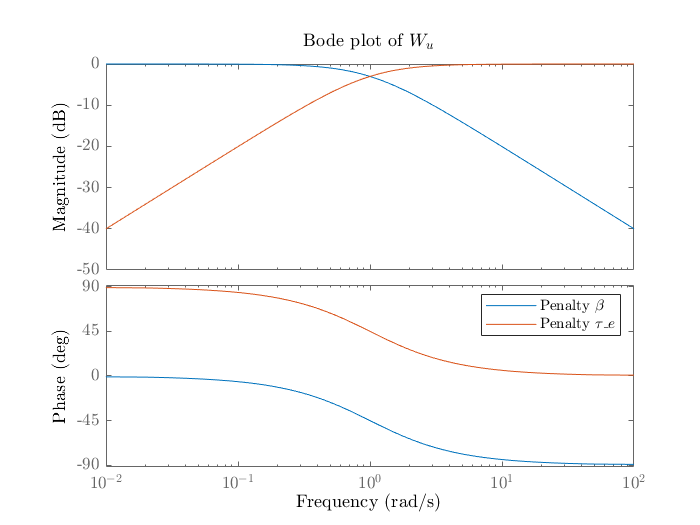

bode(tf1)
hold on
latex_bode(tf2, "$W_u$")
legend("Penalty $\beta$", "Penalty ${\tau}_{e}$")
saveas(gcf, 'Figures/ch3_mimo_weights_u_filter.eps',  'epsc')

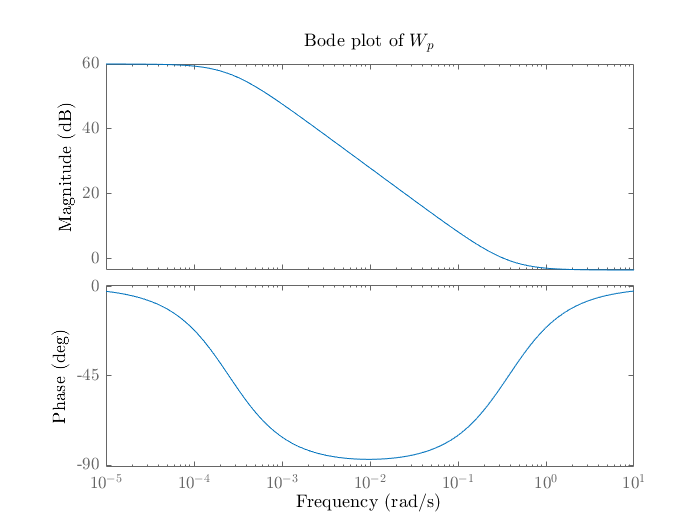


figure()
latex_bode(Wp, "$W_p$")
saveas(gcf, 'Figures/ch3_mimo_weights_p_filter.eps',  'epsc')

execute H_inf synthesis

load('Assignment_Data_SC42145.mat');
G = tf(FWT(1,1:2));


Wu = [tf1 0; 0 tf2];
P11=[Wp; zeros(size(Wu,2),size(Wp,1))]; P12=[Wp*(G); Wu]; P21=eye(size(Wp)); P22=G;
P = [P11 P12; P21 P22];

% H-infinity norm synthesis
[K, CL, gamma,syn_info] = hinfsyn(P, 1, 2); %2 inputs, 2 outputs


H_inf_norm_CL = gamma

H_inf_norm_CL = 3.0655



%define inputnames of K
K.InputName = {'dOmega'};
K.OutputName = {'Beta (deg)'; 'tau_e (Nm)'};
dOmega_sum = sumblk('dOmega = r - Omega (rad/s)');

reference tracking of $\omega_r$ and disturbance rejection of V

%build closed loop transfer function

%first connect sum block with K by connecting inputs and outputs
%the new model has inputs [r,Omega,z] and outputs [beta, tau]
ref_tf = connect(dOmega_sum, -K,  {'r';'Omega (rad/s)'},{'Beta (deg)';'tau_e (Nm)'});

%these outputs are connected as inputs of the plant
%the inputs of the connected system are the exogenous inputs [r,V]
%we would like to monitor [r,z,Omega,tau,V], so these are the chosen outputs
outputs_ = {'r';'V (m/s)';'Omega (rad/s)'; 'Beta (deg)';'tau_e (Nm)'};
closed_loop = connect(ref_tf, FWT, {'r';'V (m/s)'}, outputs_);

closed_loop = minreal(closed_loop);

22 states removed.


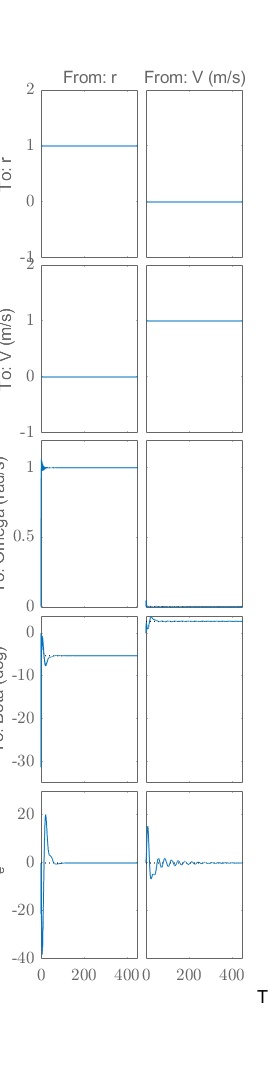


clf

figsize = [0,0,6,4 *6];

figure('units','inch','position',figsize);

set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
step(closed_loop)

%[Y_sim, T_sim] = step(closed_loop);
axs= findobj(allchild(gcf), 'flat', 'Type', 'axes');

%exogenous inputs
axs(12).YColor='Blue';

Unrecognized property 'YColor' for class 'matlab.graphics.GraphicsPlaceholder'.

axs(13).YColor='Blue';
axs(7).YColor='Blue';
axs(6).YColor='Blue';

%outputs
axs(11).YColor='Red';
axs(10).YColor='Red';
axs(5).YColor='Red';
axs(4).YColor='Red';

%control inputs
axs(9).YColor='Magenta';
axs(8).YColor='Magenta';
axs(3).YColor='Magenta';
axs(2).YColor='Magenta';

set(gcf,'Visible','on')
xlabel('Time',"interpreter",'latex')
ylabel('Amplitude',"interpreter",'latex')
for i_ax = 7:13
    axs(i_ax).YLabel.Interpreter = 'latex';
end
hs = findall(gcf, 'type', 'axes');
for i= 1:length(hs)
    ha = get(hs(i), 'title');
    ha.Interpreter = 'latex';
end

saveas(gcf, 'Figures/ch2_mimo_simulation.eps',  'epsc')


simulation with input wind 

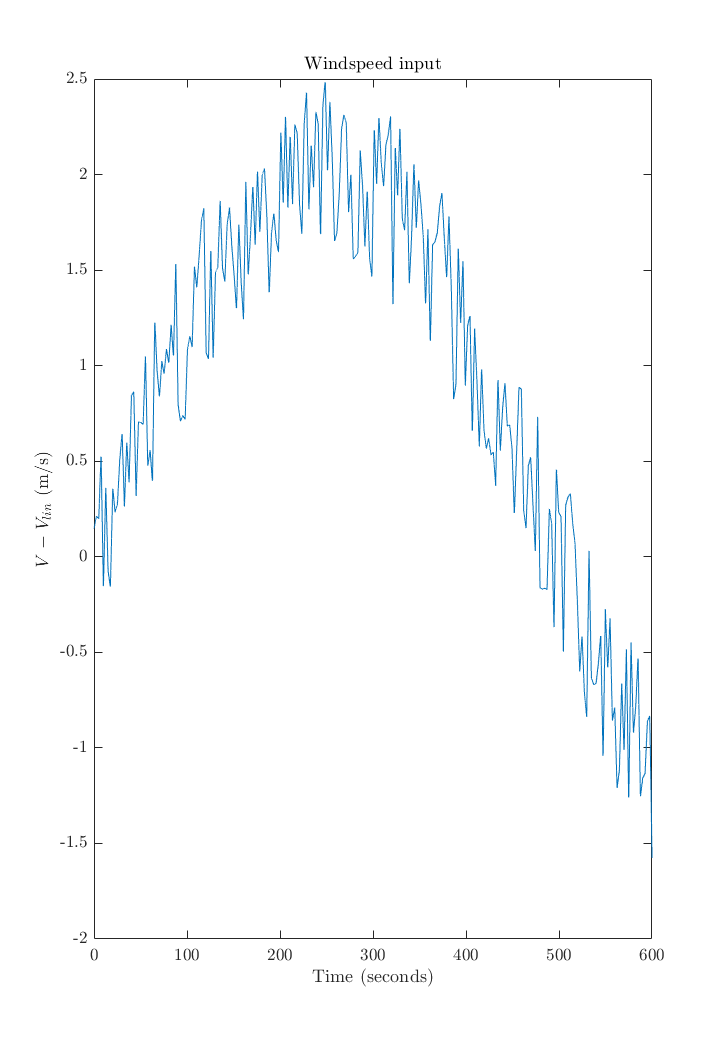

plot(Wind_Data)
set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
xlabel("Time (seconds)", 'interpreter', 'latex')
ylabel("$V-V_{lin}$ (m/s)", 'interpreter', 'latex')
title("Windspeed input", 'interpreter', 'latex')
saveas(gcf, 'Figures/ch3_wind_input.eps',  'epsc')

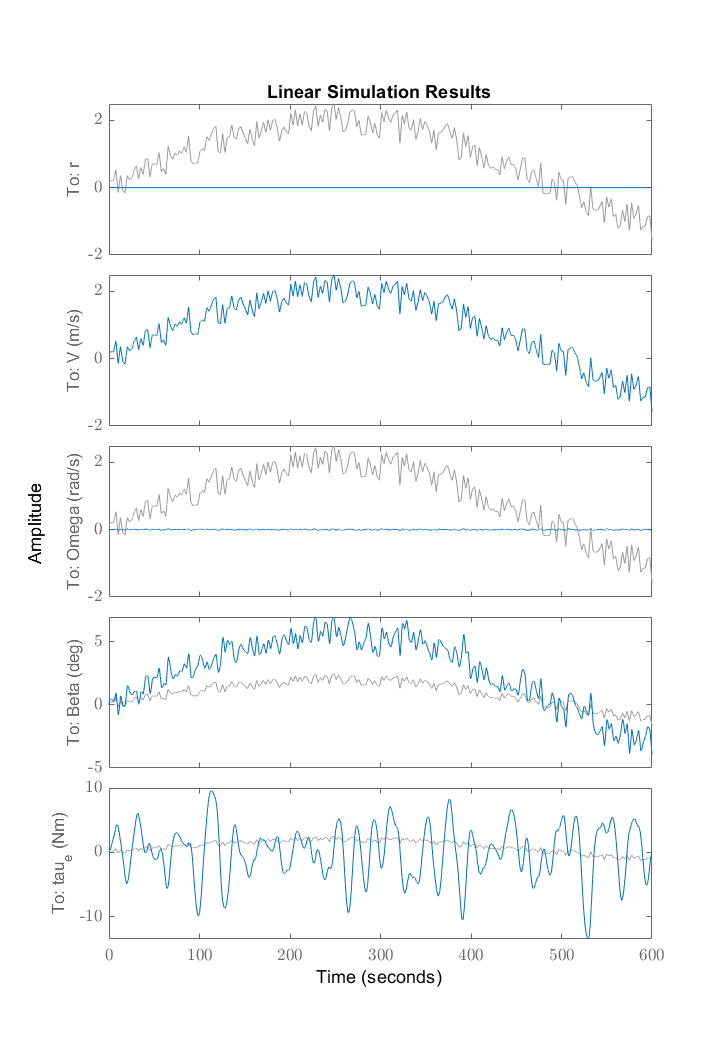

%to resample the input to evenly spaced timesteps:
t_d = Wind_Data.Time;
dt = mean(diff(t_d));
t = min(t_d):dt:max(t_d);
u = resample(Wind_Data,t);

lsim(closed_loop(:,2), u.Data,t);